In questa sezione il programma permette di allenare l'IA inserendo le foto dei soggetti che si vogliono far riconoscere nella cartella 'MerchData.zip' (Le foto che si vogliono far riconoscere devono essere inserite in delle sottocartelle intitolate nel modo in cui vogliamo che esse vengano denominate dall'IA). Il programma consente di inserire al massimo 5 nuovi soggetti ma questo vincolo può essere modificato. Nell'esecuzione della sezione viene visualizzato il grafico dell'apprendimento della rete neurale relativo alle foto inserite nella cartella.

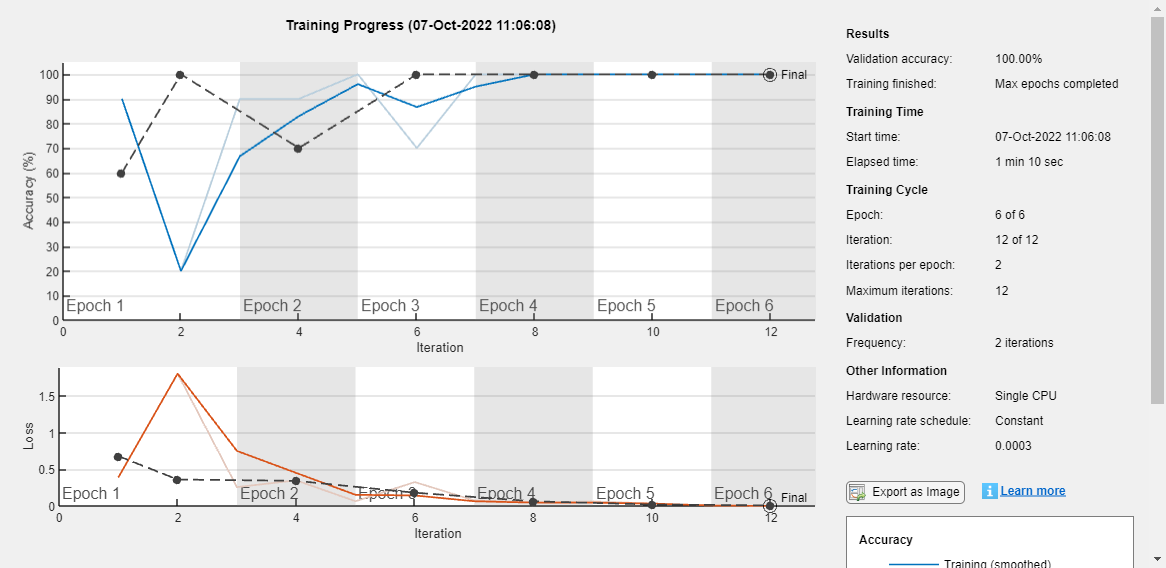

unzip('MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7);
net=googlenet;
net.Layers(1);
inputSize = net.Layers(1).InputSize;
lgraph = layerGraph(net);
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];
numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(augimdsTrain,lgraph,options);

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 1

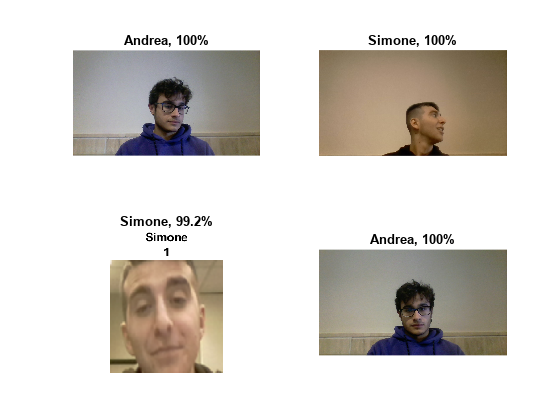

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

Questa sezione di codice permette di scattare una foto dalla webcam, visualizzandola successivamente con il relativo riconoscimento fornito dall'IA. Viene inoltre fornita la probabilità che l'IA attribuisce all'identificazione del soggetto fotografato.

camera = webcam;
inputSize1 = net.Layers(1).InputSize(1:2);

inputSize1 =    224   224


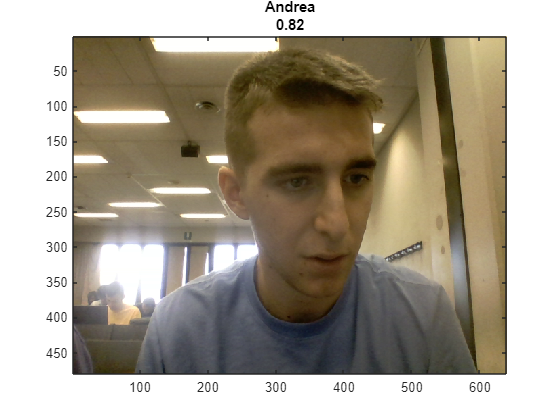

figure
im = snapshot(camera);
image(im)
im = imresize(im,inputSize1);
[label,score] = classify(net,im);
title({char(label),num2str(max(score),2)});

Questa sezione di codice permette di identificare un volto nella foto scattata dalla sezione precedente, in particolare i volti identificati vengono riquadrati in rosso e viene fornito il numero di volti rilevati dall'IA nell'immagine.

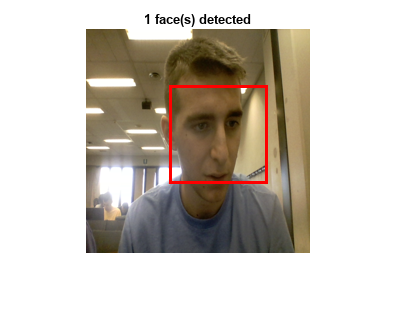

figure
detector = vision.CascadeObjectDetector;
bbox = detector(im);
videoOut = insertShape(im,'Rectangle',bbox,'Color','r','LineWidth',3);
imshow(videoOut);
title(sprintf(' %d face(s) detected ',size(bbox,1)));

Questa sezione di codice permette di visualizzare i volti inquadrati dalla webcam ritagliati e identificati dall'IA.

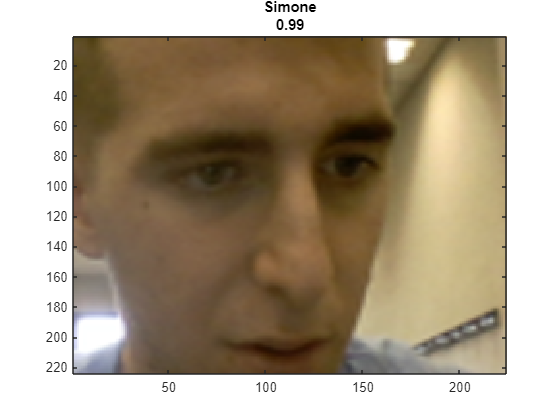

figure
cutImage=imcrop(im,bbox);
cutImage = imresize(cutImage,inputSize1);
image(cutImage);
[label,score] = classify(net,cutImage);
title({char(label),num2str(max(score),2)});

clear camera;

Questa sezione di codice permette di eseguire le 3 sezioni precedenti nella stessa figura.

camera = webcam;
inputSize1 = net.Layers(1).InputSize(1:2)

inputSize1 =    224   224


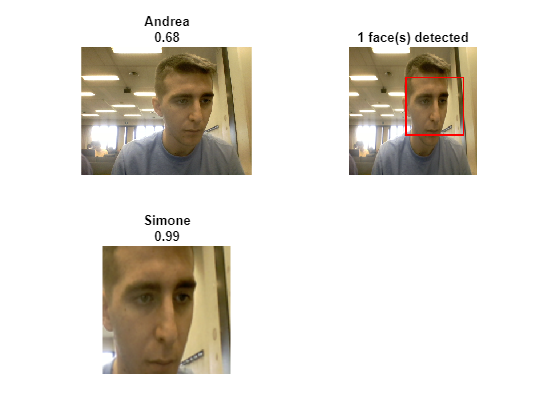

figure
im = snapshot(camera);
subplot(2,2,1),imshow(im)
im = imresize(im,inputSize1);
[label,score] = classify(net,im);
title({char(label),num2str(max(score),2)});
detector = vision.CascadeObjectDetector;
bbox = detector(im);
videoOut = insertShape(im,'Rectangle',bbox,'Color','r','LineWidth',3);
subplot(2,2,2),imshow(videoOut)
title(sprintf(' %d face(s) detected ',size(bbox,1)));
cutImage=imcrop(im,bbox);
cutImage = imresize(cutImage,inputSize1);
subplot(2,2,3),imshow(cutImage)
[label,score] = classify(net,cutImage);
title({char(label),num2str(max(score),2)});

clear camera;

Questa sezione compie una serie di foto finchè l'IA non rileva un volto, a quel punto stampa il volto con la relativa identificazione.

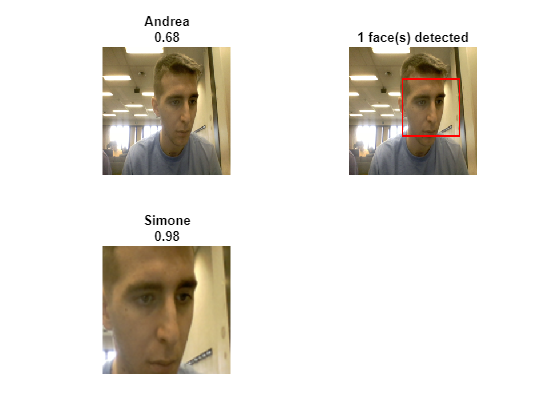

camera = webcam;
detector = vision.CascadeObjectDetector;
im = snapshot(camera);
inputSize1 = net.Layers(1).InputSize(1:2);
im = imresize(im,inputSize1);

while size(detector(im))==[0,4]
im = snapshot(camera);
im = imresize(im,inputSize1);
pause(0.2)
end

figure
subplot(2,2,1),imshow(im)
[label,score] = classify(net,im);
title({char(label),num2str(max(score),2)});
bbox = detector(im);
videoOut = insertShape(im,'Rectangle',bbox,'Color','r','LineWidth',3);
subplot(2,2,2),imshow(videoOut)
title(sprintf(' %d face(s) detected ',size(bbox,1)));

if size(detector(im)) == [1,4]
cutImage=imcrop(im,bbox);
cutImage=imresize(cutImage,inputSize1);
subplot(2,2,3),imshow(cutImage)
[label,score] = classify(net,cutImage);
title({char(label),num2str(max(score),2)});
end

Questa sezione se mandata in esecuzione dopo la precedente permette di stampare separatamente tutti i volti identificati con il relativo riconoscimento.

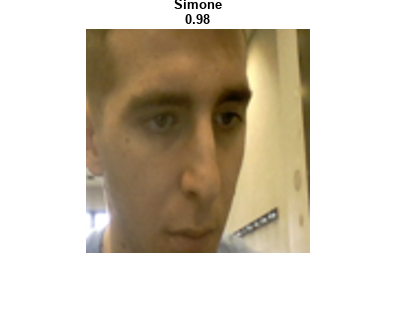

numeroPersone=size(detector(im),(1));
facce=char(1,numeroPersone);
i=1;
while i<=numeroPersone
    figure
    appoggio=imcrop(im,[bbox(i,1) bbox(i,2) bbox(i,3) bbox(i,4)]);
    appoggio=imresize(appoggio,inputSize1);
    imshow(appoggio);
    [label,score] = classify(net,appoggio);
    title({char(label),num2str(max(score),2)});
    pause(1);
    i=i+1;
end

clear im;
clear camera;